# **Identification of the torque/position relationship of a pendulum**

List of functions for the exam:

- sys = ss(F, G, H, D, Ts); or sys = ss(W);

- eigenvalues = eig(sys);

- O = obsv(sys);

- R = ctrb(sys);

- obs_rank = rank(O);

- W = tf(sys);  or  W = tf(num_coeffs, den_coeffs, Ts);

- W = zpk(W);

- zeros_vec = zero(W);

- pole_vec = pole(W);

- sys_gain = dcgain(W);

- bode(sys)

- impulse(sys)

- step(sys)

- lsim(sys)

- sys = n4sid(data) *

- [U, S, V] = svd(Hqd) *

*shown in this example.

**In this example, we apply the 4SID method to identify a model describing the behavior of a pendulum.**

close all
clearvars

The data-generating system is described by the mathematical model of the pendulum linearized around $\alpha =0$ 


$$\ddot{\alpha}(t) = \frac{1}{m\ell^{2}}\tau(t)-\frac{c}{m\ell^{2}}\dot{\alpha}(t)+mg\ell\sin{(\!\alpha(t)\!)}$$


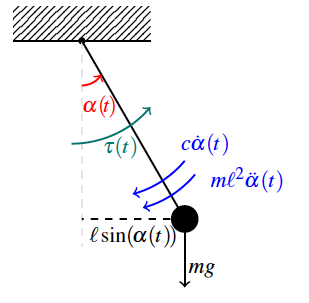

%% System parameters 
m    = 1;               % [kg]      mass
l    = 0.5;             % [m]       rod length
g    = 9.81;            % [m/s^2]   gravitational acceleration 
c    = 1;               % [Nms]  damping coefficient
Ts   = 0.01;            % [s]       sampling time (100 Hz)

We simulate the data-generating system through the following Simulink model 

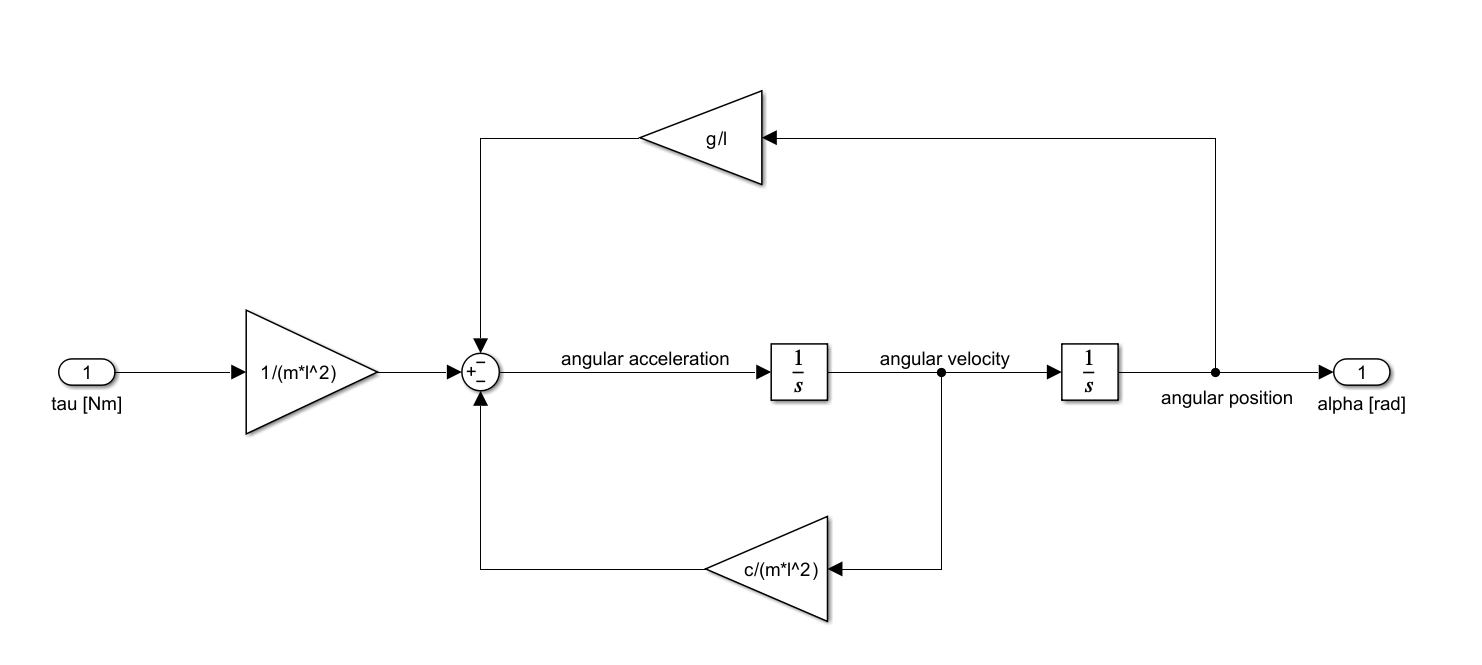

This model is embbedded within the Simulink scheme

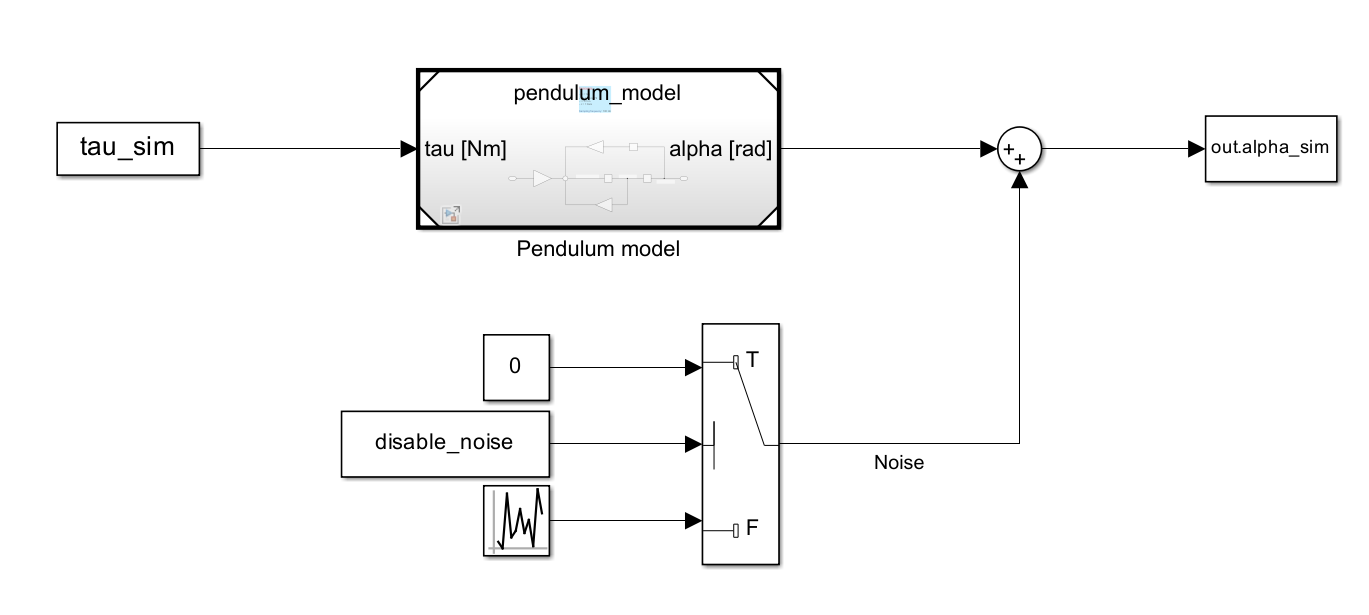

that allows us to account for the two configurations we consider:

- Noise-free case

- Noisy case

## Identification:  Impulse response - Noiseless case

We perform exactly the same steps followed in the excercises.

#### Input definition

N    = 400;              % []       number of measurement
Tf   = Ts*(N-1);        % [s]       simulation duration
time = 0:Ts:Tf;         % [s]       time vector

% We use the impulse response to identify a model for the system
u_impulse     = zeros(1,N);
u_impulse(1)  = 50;                                       
tau_sim       = timeseries(u_impulse,time); % Needed to inteface the 
                                            % code with Simulink

#### Simulation

disable_noise = true;     % true = mesurements without noise 

out = sim('pendulum_sim');
y_irnf = out.alpha_sim;   % [rad] saved from the simulink scheme 

#### Experimental setup - plots

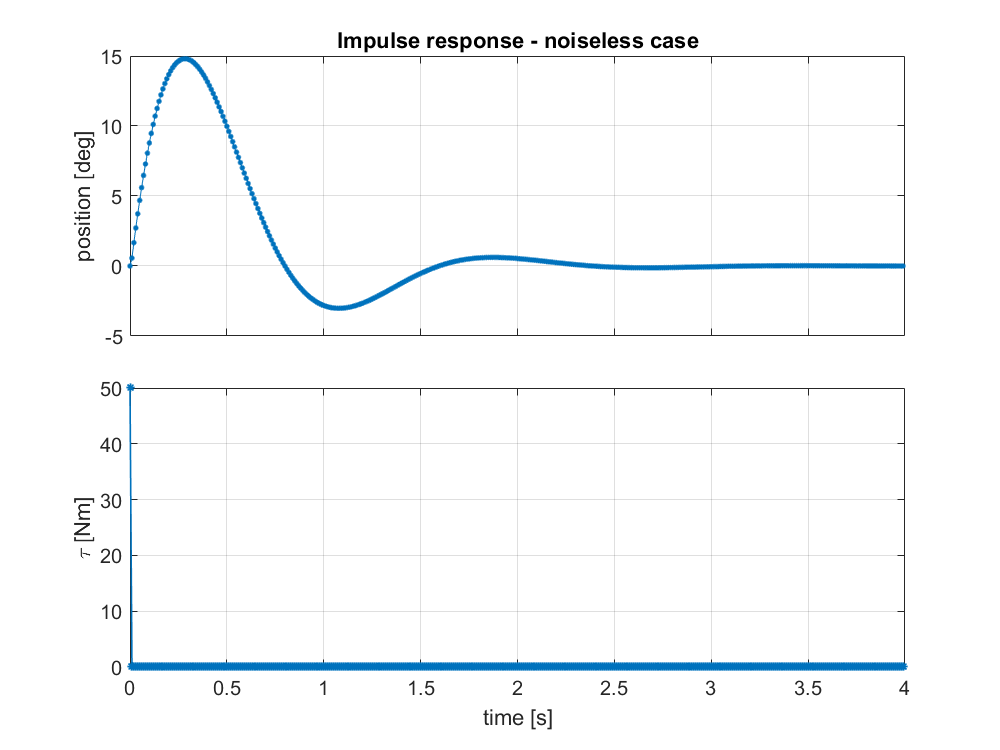

%% experiment plot
figure;
tiledlayout(2, 1, 'TileSpacing', 'compact');

ax(1) = nexttile; hold on; grid on; box on;
title('Impulse response - noiseless case');
set(gca,'FontSize',12,'DefaultLineLineWidth',0.5);
plot(time,y_irnf*180/pi,'Marker','.','MarkerSize',10);
ylabel('position [deg]');

ax(2) = nexttile; hold on; grid on; box on;
set(gca,'FontSize', 12, 'DefaultLineLineWidth', 1);
xlabel('time [s]');
ylabel('\tau [Nm]');
plot(time, u_impulse, 'marker', '*', 'MarkerSize', 5);

set(gcf, 'position', [0,0,800,600]);

ax(1).XTickLabel = '';
linkaxes(ax, 'x'); clear ax;  clf;

#### Hankel matrix computation 

To determine the order of the model we compute the Hankel matrix


$$H_{N}= \left[ \matrix{\omega(1) & \omega(2) & \cdots & \omega(N) \cr

\omega(2) & \omega(3) & \cdots & \omega(N+1)\cr
\vdots & \vdots & \ddots & \vdots \cr
\cr
\omega(N) & \omega(N+1) & \ldots & \omega(2N-1)
}\right]$$


and check its rank. As soon as we find $\textrm{rank}\left(H_{n+1} \right)=\textrm{rank}\left(H_n \right)$ we have retrieved the order of the system. 

(Hint: increasing order from 1 up to 3 - since we know the true order of the system is 2)

(Remark: this strategy is likely not to work if the data are noisy - in this case we do not care since the data are noiseless)

% Matlab indexing starts from 1 not from 0!!! 
% omega(0) = y(1); omega(1)=y(2); omega(2)=y(3) and so on ...

H1 = [y_irnf(2)];

H2 = [y_irnf(2) y_irnf(3)
      y_irnf(3) y_irnf(4)];

H3 = [y_irnf(2) y_irnf(3) y_irnf(4)
      y_irnf(3) y_irnf(4) y_irnf(5)
      y_irnf(4) y_irnf(5) y_irnf(6)];
  
rH1 = rank(H1);
rH2 = rank(H2);
rH3 = rank(H3);

disp(['The rank of H1 is: ' num2str(rH1)]);

The rank of H1 is: 1


disp(['The rank of H2 is: ' num2str(rH2)]);

The rank of H2 is: 2


disp(['The rank of H3 is: ' num2str(rH3)]);

The rank of H3 is: 2


**As you can see from the obtained results, the true order of the system is recovered!**

Accordingly, we pick the order of the system

n = 2;

#### Factorization of $H_3$ ($H_{n+1}$)

We know that $H_3$ has 2 out of 3 linearly independent rows. We use two of them to construct $R_3$ and then we obtain $O_3$ so as to reconstruct $H_3$ ($H_3 =O_3 \cdot R_3$)  

R3 = H3(1:2,:);     % put in R3 2 indipendent rows of H3 

% To reconstruct H3 through O3*R3 we have to find the linear relationship
% between the two independent rows and the remaining one
% To do so we solve the linear system Ax=b, with A=H3(1:2,:) and b=H3(3,:)'
A = H3(1:2,:)';     
b = H3(3,:)';
x = linsolve(A,b);


O3 = [ 1        0;
       0        1;
      x(1)    x(2)];

#### Matrix extraction & estimated transfer function computation

We have to retrieve the matrices of the model 


$$\left\{\matrix{ x(t+1)=\hat{F}x(t)+\hat{G}u(t) \cr \hat{y}(t)=\hat{H}x(t)}$$


Based on what you have seen in class $\hat{H}=O_{3}(1,:)$,$\hat{G}=R_{3}(:,1)
$ and $\hat{F}=(O_{3}(1:n,:))^{-1}O_{3}(2:n+1,:)$

D_hat = y_irnf(1); 
H_hat = O3(1,:);                            % first row of O_n+1
G_hat = R3(:,1)/u_impulse(1);              % first column  of R_n+1
F_hat = O3(1:n,:)\O3(2:n+1,:);         % inverse of the first n rows of
                                            % O_n+1 times its last n rows

% Estimated transfer function computation
sys   = ss(F_hat,G_hat,H_hat,D_hat,Ts);
W_hat = tf(sys);

#### Validation (simulations and comparison plots)

To validate the model, we feed the data-generating system and the estimated model with the same input and we compare the resulting outputs.

% Input definition
step_time      = 1;
step_amplitude = 2;

u_val         = step_amplitude*(time >= step_time);    % step input 
tau_sim       = timeseries(u_val,time);         

out = sim('pendulum_sim');
y_valnf        = out.alpha_sim;                           % true output
y_val_hat    = lsim(W_hat,u_val,time);                  % simulated output      


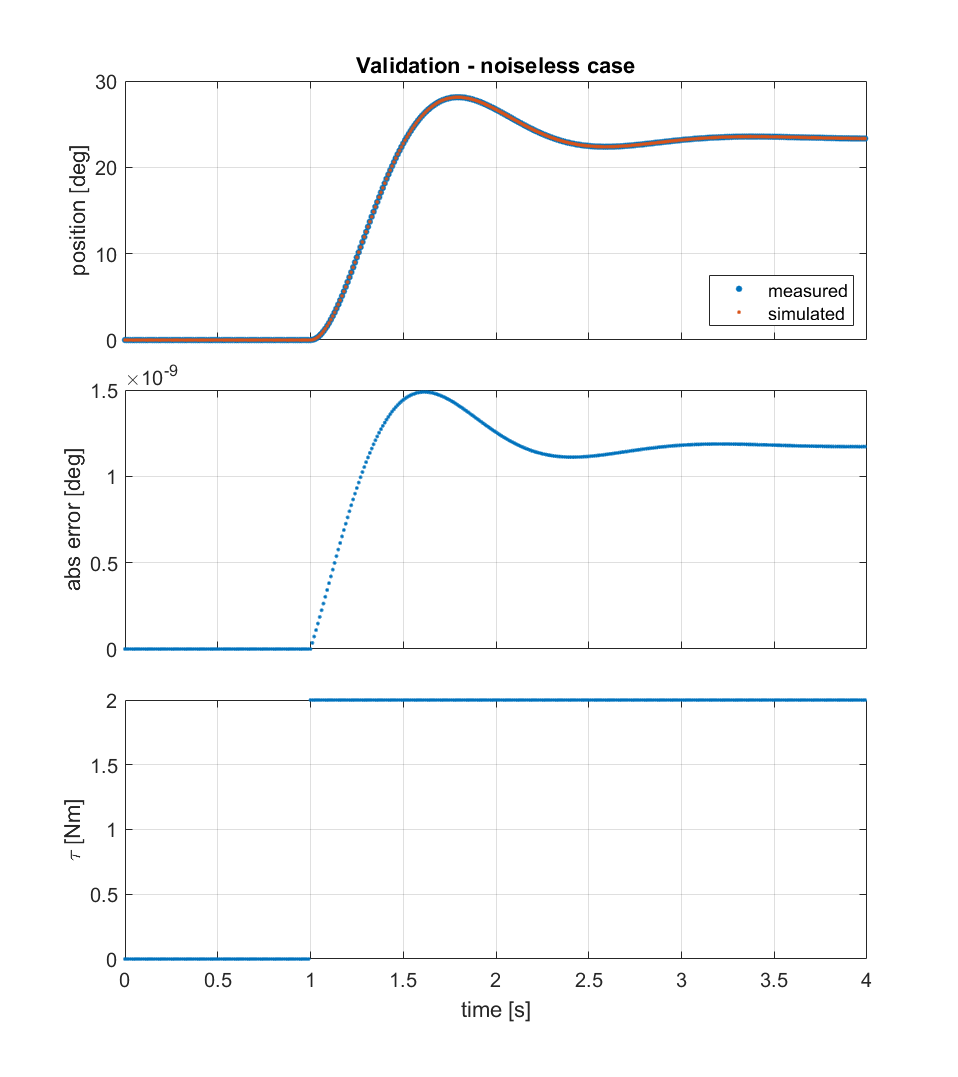

%% Plots
figure;
tiledlayout(3, 1, 'TileSpacing', 'compact');

ax(1) = nexttile; hold on; grid on; box on;
title('Validation - noiseless case');
set(gca,'DefaultLineLineWidth', 0.5,'FontSize',12); 
plot(time, y_valnf*180/pi, '.', 'MarkerSize', 12)
plot(time, y_val_hat*180/pi, '.');
legend('measured', 'simulated', 'location', 'SouthEast');                                
ylabel('position [deg]');

ax(2) = nexttile; hold on; grid on; box on;
set(gca,'DefaultLineLineWidth', 0.5, 'FontSize',12);                      
ylabel('abs error [deg]');
plot(time, abs(y_val_hat-y_valnf)*180/pi, '.')

ax(3) = nexttile; hold on; grid on; box on;
set(gca,'DefaultLineLineWidth', 0.5, 'FontSize',12);
xlabel('time [s]');                                                         
ylabel('\tau [Nm]');
plot(time,u_val,'.');

set(gcf,'position',[0,0,800,900]);

ax(1).XTickLabel = '';
ax(2).XTickLabel = '';
linkaxes(ax,'x'); clear ax;  clf;

As it can be noticed, the measured and estimated positions almost overlap (as confirmed by the absolute error reported in the second plot). Thus, the model retrieved from data accurately describe the behavior of the actual data-generating system (as expected, since we work in a noiseless setting).  

## Identification: Impulse response - Noisy case

We consider now the case in which the measure outputs are corrupted by noise, i.e.,


$$y(t)=y_{\mathrm{o}}(t)+v(t), \qquad  v(t)\sim wn(0,\sigma^2)$$


#### Simulation

tau_sim       = timeseries(u_impulse,time); % Needed to inteface the 
                                            % code with Simulink
disable_noise = false;     % false = mesurements with noise 

out = sim('pendulum_sim');
y_ir = out.alpha_sim;   % [rad] saved from the simulink scheme 

#### Experimental setup - plots

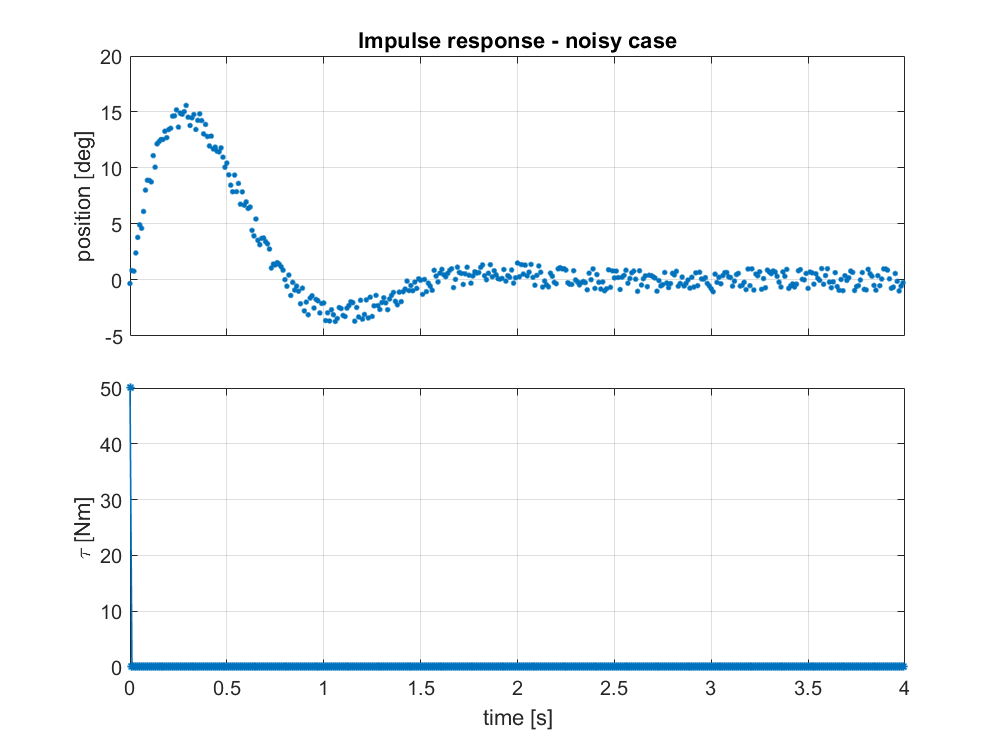

%% experiment plot
figure;
tiledlayout(2, 1, 'TileSpacing', 'compact');

clearvars ax;
ax(1) = nexttile; hold on; grid on; box on;
title('Impulse response - noisy case');
set(gca,'FontSize',12,'DefaultLineLineWidth',0.5);
plot(time,y_ir*180/pi,'.','MarkerSize',10);
ylabel('position [deg]');

ax(2) = nexttile; hold on; grid on; box on;
set(gca,'FontSize',12,'DefaultLineLineWidth',1);
xlabel('time [s]');
ylabel('\tau [Nm]');
plot(time,u_impulse,'marker','*','MarkerSize',5);

set(gcf,'position',[0,0,800,600]);

ax(1).XTickLabel = '';
linkaxes(ax,'x'); clear ax;  clf;

By looking at the measured impulse response, we can clearly see the effect of noise. Which is even more clear if the noiseless and noisy output are directly compared.

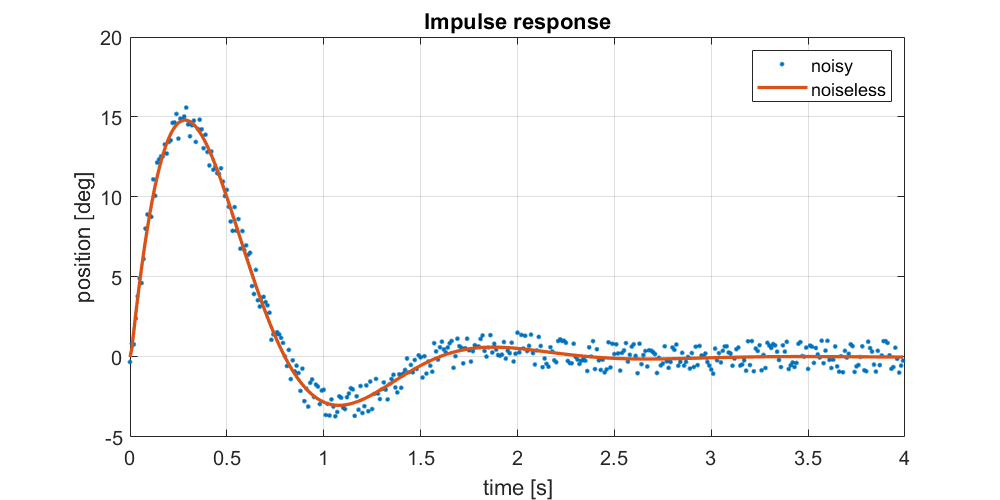

figure
title('Impulse response')
hold all, grid on, box on;
set(gca,'FontSize',12,'DefaultLineLineWidth',0.9);
xlabel('time [s]');
ylabel('position [deg]');
plot(time,y_ir*180/pi, '.','MarkerSize',8);
hold on
plot(time,y_irnf*180/pi, 'LineWidth', 2);
legend('noisy','noiseless');

set(gcf,'position',[0,0,800,400]); clf;

#### Hankel matrix computation 

To determine the order of the model we compute the Hankel matrix


$$H_{N}= \left[ \matrix{\omega(1) & \omega(2) & \cdots & \omega(N) \cr

\omega(2) & \omega(3) & \cdots & \omega(N+1)\cr
\vdots & \vdots & \ddots & \vdots \cr
\cr
\omega(N) & \omega(N+1) & \ldots & \omega(2N-1)
}\right]$$


and check its rank. As soon as we find $\textrm{rank}\left(H_{n+1} \right)=\textrm{rank}\left(H_n \right)$ we have retrieved the order of the system. 

(We increasing N from 1 up to 4 - since we know the true order of the system is 2 but we have noise corrupting data)

% Matlab indexing starts from 1 not from 0!!! 
% omega(0) = y(1); omega(1)=y(2); omega(2)=y(3) and so on ...

H1 = [y_ir(2)];

H2 = [y_ir(2) y_ir(3)
      y_ir(3) y_ir(4)];

H3 = [y_ir(2) y_ir(3) y_ir(4)
      y_ir(3) y_ir(4) y_ir(5)
      y_ir(4) y_ir(5) y_ir(6)];

H4 = [y_ir(2) y_ir(3) y_ir(4) y_ir(5);
      y_ir(3) y_ir(4) y_ir(5) y_ir(6);
      y_ir(4) y_ir(5) y_ir(6) y_ir(7);
      y_ir(5) y_ir(6) y_ir(7) y_ir(8)];
  
rH1 = rank(H1);
rH2 = rank(H2);
rH3 = rank(H3);
rH4 = rank(H4);

disp(['The rank of H1 is: ' num2str(rH1)]);

The rank of H1 is: 1


disp(['The rank of H2 is: ' num2str(rH2)]);

The rank of H2 is: 2


disp(['The rank of H3 is: ' num2str(rH3)]);

The rank of H3 is: 3


disp(['The rank of H4 is: ' num2str(rH4)]);

The rank of H4 is: 4


By looking at the rank of these Hankel matrices only, we cannot deduce the order of the system as the rank keeps increasing with the dimension of the Hankel matrix (expected behavior since the data are noisy).

#### Singular value decomposition

Build a Hankel matrix using all data $\tilde{H}$ with $d$ columns and $q$ rows, such that $q+d-1=N$


$$\tilde{H}=\left[\matrix{
\omega(1) & \omega(2) & \cdots & \omega(d) \cr
\omega(2) & \omega(3) & \cdots & \omega(d+1) \cr
\vdots & \vdots & \ddots & \vdots \cr
\omega(q) & \omega(q+1) & \cdots & \omega(d+q-1)
}\right]$$


remembering that:

-  $q \simeq d$ leads to better accuracy

- $q \ll d
$ reduce the computational effort required to perform SVD

We then use *Singular Value Decomposition *(SVD) to find the singular values of $\tilde{H}$. By plotting their values, we empirically select the order of the system if we can clearly spot a jump in their values or based on the range of values characterizing the knee of the overall plot we obtain.

%% Hankel matrix construction (qxd, where q and d are design parameters)

% Rules: 
% q <= d better accuracy
% q << d lower computational complexity 

q = 190; 
d = 210;

hankel_qd = nan(q,d); % predefinition of Henkel matrix

% Henkel matrix creation 
for i_row = 1:q
   hankel_qd(i_row,:) = y_ir(i_row+1:d+i_row); 
end

%% Singular values analysis

tic
[U,S,V]  = svd(hankel_qd);    % singular values decomposition
svd_cput =  toc               % cpu time [s] needed to decompose the Hankel based on our choices

svd_cput = 0.0071


sv = diag(S);                  % singular values extraction

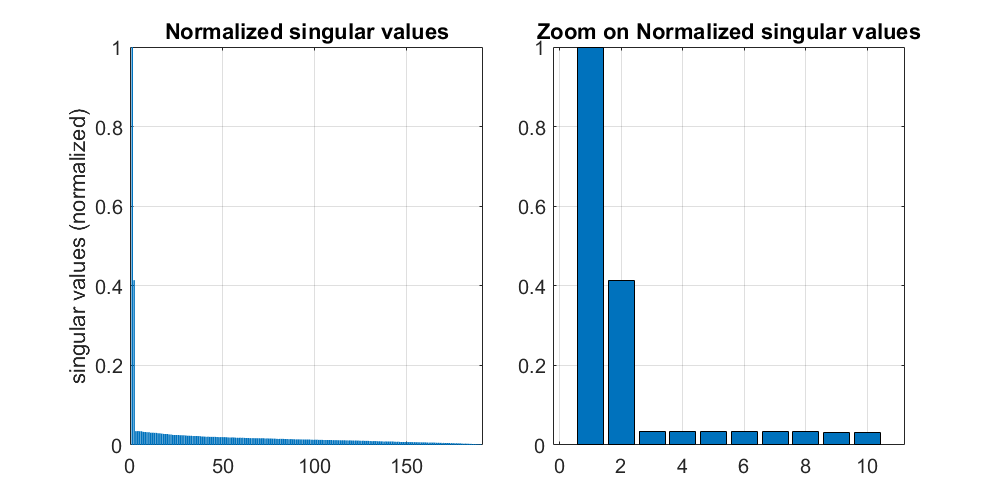


% Plot of singular values
figure;

tiledlayout(1,2,'TileSpacing','compact');

nexttile; hold all; grid on; box on;
set(gca,'FontSize',12);
ylabel('singular values (normalized)');
title('Normalized singular values')
bar(sv/max(sv),0.85); % Normalized singular values

nexttile; hold all; grid on; box on;
set(gca,'FontSize',12);
title('Zoom on Normalized singular values')
bar(sv(1:10)/max(sv(1:10)),0.85);


set(gcf,'position',[0,0,800,400]); clf;

In this case, there is a clear jump between the third and the second singular values. Thus, we pick the order of the system:

n = 2;

**We have once again recovered the true order of the data-generating system!**

#### Matrix extraction & estimated transfer function computation

We use the matrices obtained with the SVD ( $U,V$ and $S$) to estimate the matrices of the model


$$\left\{\matrix{ x(t+1)=\hat{F}x(t)+\hat{G}u(t) \cr \hat{y}(t)=\hat{H}x(t)}$$


In particular, based on what you have seen in class

$\hat{O}=\hat{U}\hat{S}^{1/2}~~~~~~~~~\hat{R}=\hat{S}^{1/2}\hat{V}^{T}       $       being       $\hat{U}=U(:,1:n)~~~~~~~~~\hat{V}^T=V^T(1:n,:)~~~~~~~~~\hat{S}=S(1:n,1:n)$

and set $\hat{H}=\hat{O}(1,:)$,  $\hat{G}=\hat{R}(:,1)
$ and $\hat{F}=[(\hat{O}(1:n,:))^{T}\hat{O}(1:n,:)]^{-1}(\hat{O}(1:n,:))^{T}\hat{O}(2:n+1,:)$ (we need to use the pesudo-inverse and, thus, the corresponding MATLAB command, since $\hat{O}(1:n,:)$ is not square) 

V_tr = V';    % V matrix transpose

U_hat    = U(:,1:n);
S_hat    = S(1:n,1:n);
V_hat_tr = V_tr(1:n,:);

%Construct the approximated observability and reachability matricies
O_hat = U_hat*sqrtm(S_hat);
R_hat = sqrtm(S_hat)*V_hat_tr;

H_hat = O_hat(1,:);
G_hat = R_hat(:,1)/u_impulse(1);     

O_hat1 = O_hat(1:q-1,:);
O_hat2 = O_hat(2:q,:);

F_hat = pinv(O_hat1)*O_hat2;   % Ohat_1 is rectangular --> we use 
                               % the pseudo-inverse 
D_hat = 0;

% Estimated transfer function computation
sys   = ss(F_hat,G_hat,H_hat,D_hat,Ts);
W_hat = tf(sys);

#### Validation (simulations and comparison plots)

We validate the model in the same conditions as before.

% Input definition
step_time      = 1;
step_amplitude = 2;

u_val         = step_amplitude*(time >= step_time);    % step input 
tau_sim       = timeseries(u_val,time);         

out = sim('pendulum_sim');
y_val        = out.alpha_sim;                           % true output
y_val_hat    = lsim(W_hat,u_val,time);                  % simulated output      


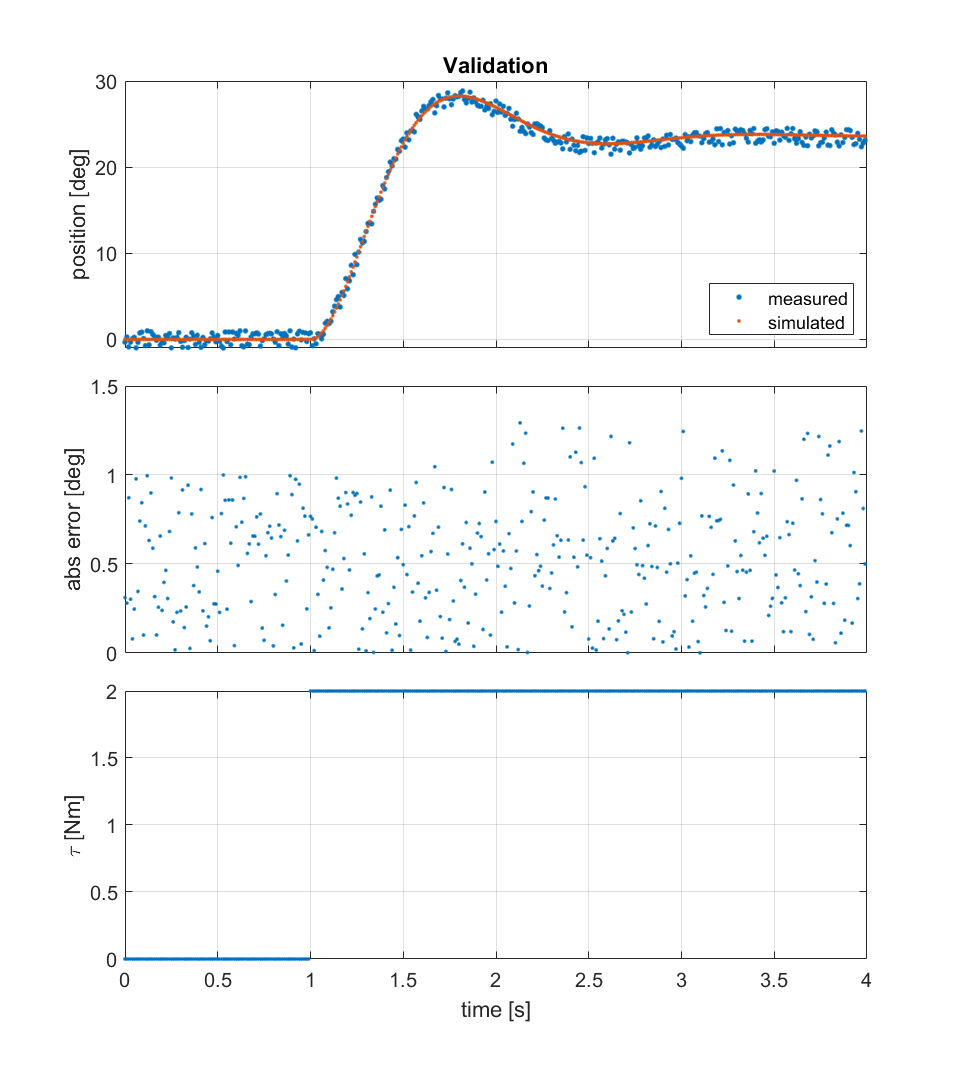

%% Plots
figure;
tiledlayout(3, 1, 'TileSpacing', 'compact');

clearvars ax;
ax(1) = nexttile; hold on; grid on; box on;
title('Validation');
set(gca,'DefaultLineLineWidth', 0.5,'FontSize',12);
plot(time,y_val*180/pi,'.','MarkerSize', 10);
plot(time,y_val_hat*180/pi,'.');                                             
ylabel('position [deg]');
legend('measured','simulated','location','SouthEast');

ax(2) = nexttile; hold on; grid on; box on;
hold all, grid on, box on;
set(gca,'DefaultLineLineWidth', 0.5,...
    'FontSize',12);
plot(time,abs(y_val_hat-y_val)*180/pi,'.');                                              
ylabel('abs error [deg]');

ax(3) = nexttile; hold on; grid on; box on;
hold all, grid on, box on;
set(gca,'DefaultLineLineWidth', 0.5,...
    'FontSize',12);
xlabel('time [s]');                                                         
ylabel('\tau [Nm]');
plot(time,u_val,'.');

set(gcf,'position',[0,0,800,900]);

ax(1).XTickLabel = '';
ax(2).XTickLabel = '';
linkaxes(ax,'x'); clear ax;  clf;

By looking at the comparison reported above, it is clear that the the simulated output matches with less accuracy the actual (noisy) output of the data-generating system. This can be directly linked to the introduction of noise. This result might be improved by changing the parameters $d$ and $q$ (the only degrees of freedom available). 

(Hint: i) try to check the effect of different level of noise - to be changed inside the Simulink scheme; ii) try different parameters $d$ and $q$ to check their effect on both the quality of the model and the computational time; iii) check what happens if we use the standard impulse, namely by setting u_impulse(1)=1) 

## Identification (General case)

In this case we consider a more general (and realistic) input and we use the 4SID command of MATLAB. The identification procedure is carried out once more by corrupting the outputs with measurement noise.

N    = 10000;           % []        number of measurement
Tf   = Ts*(N-1);        % [s]       simulation duration
time = 0:Ts:Tf;         % [s]       time vector

% We choose to use a filtered white gaussian noise as input (It is important for the signal to 
% sufficiently excite the system, so as to have informative data)

u_wgn = wgn(1,N,20);    % Definition of the unfiltered input sequence - realization of a white 
                        % Gaussian noise with power equal to 20 dBW

% white gaussian noise filtering
s          = tf('s');
LP_freq    = 5;                                 % LP filter bandwith
LP_filter  = 1/(s/(2*pi*LP_freq)+1);            % first order LP filter
u_exp = lsim(LP_filter, u_wgn, time);      % white gaussian noise filtering

tau_sim = timeseries(u_exp,time);

#### Simulation

disable_noise = false;     % false = measurements with noise

out = sim('pendulum_sim');    
y_exp = out.alpha_sim;  

#### Experimental setup - plots

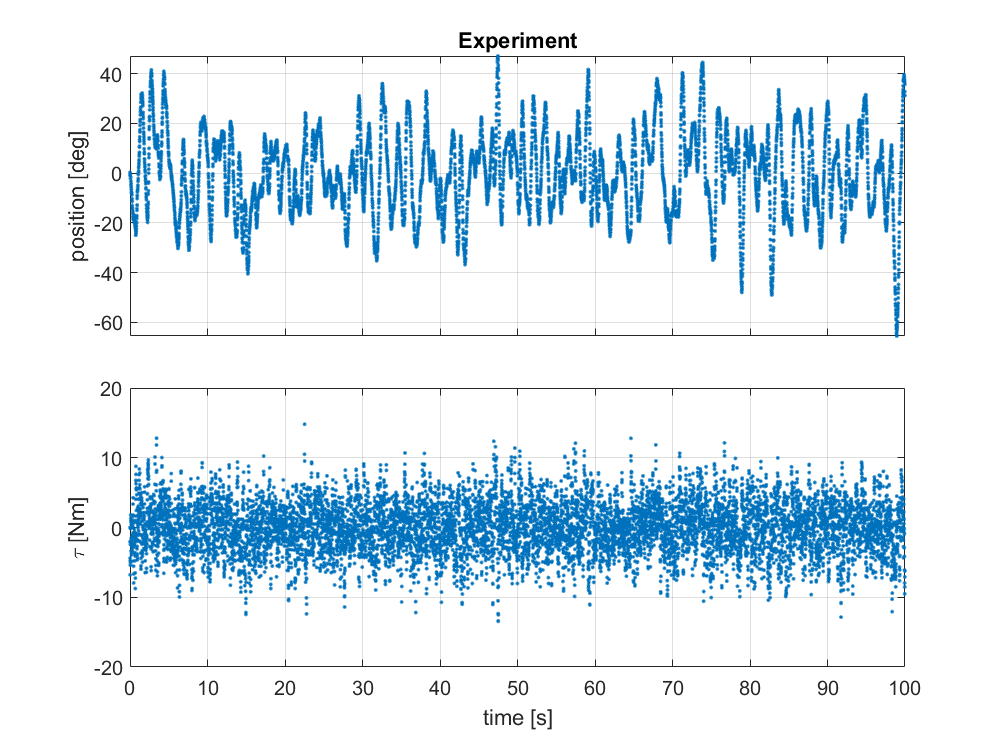

%% experiment plot
figure;
tiledlayout(2, 1, 'TileSpacing', 'compact');

clearvars ax;
ax(1) = nexttile; hold on; grid on; box on;
title('Experiment');
set(gca,'FontSize',12,'DefaultLineLineWidth',0.5);
plot(time,y_exp*180/pi,'.');
ylabel('position [deg]');

ax(2) = nexttile; hold on; grid on; box on;
set(gca,'FontSize',12,'DefaultLineLineWidth',0.5);
plot(time,u_exp,'.');
xlabel('time [s]');
ylabel('\tau [Nm]');

set(gcf,'position',[0,0,800,600]);

ax(1).XTickLabel = '';
linkaxes(ax,'x'); clear ax;  clf;

As you can see, the input fed to the system to obtain the experimental data is not an impulse any longer.

In this case we have to select the order of the model a-priori. If the order is too low, you end up with an incorret model while if the order is excessively high the model is over-parametrized, leading to poor performance when used to approximate the behavior of the data-generating system. Since we know that the pendulum is a system of the second order, we pick

n = 2;  

In reality, we might not know this. There are data-driven techniques that allow one to select the order of the model. 

(Hints: try to check what happens by changing n)

#### Identification of a 2nd order model for the pendulum

We exploit an additional prior on the system (the fact that we are considering its behavior around the stable equilibrium point only), enforcing stability of the identified model (thorugh the options of the n4sid function)

data     = iddata(y_exp, u_exp, Ts);    % For the data to be digested by the 
                                        % default n4sid function
n4sidopt = n4sidOptions('EnforceStability', true);      
sys      = n4sid(data, n, n4sidopt);   

#### Model and estimated transfer function

F = sys.A;
G = sys.B;
H = sys.C;
D = sys.D;

W_hat  = tf(ss(F,G,H,D,Ts));

#### Validation

We validate the model in the same conditions considered initially.

step_time      = 1;
step_amplitude = 2;

u_val        = step_amplitude*(time >= step_time);            % step input definition
tau_sim      = timeseries(u_val,time);                        % simulation input definition

out = sim('pendulum_sim');
y_val        = out.alpha_sim;
y_val_hat    = lsim(W_hat,u_val,time);


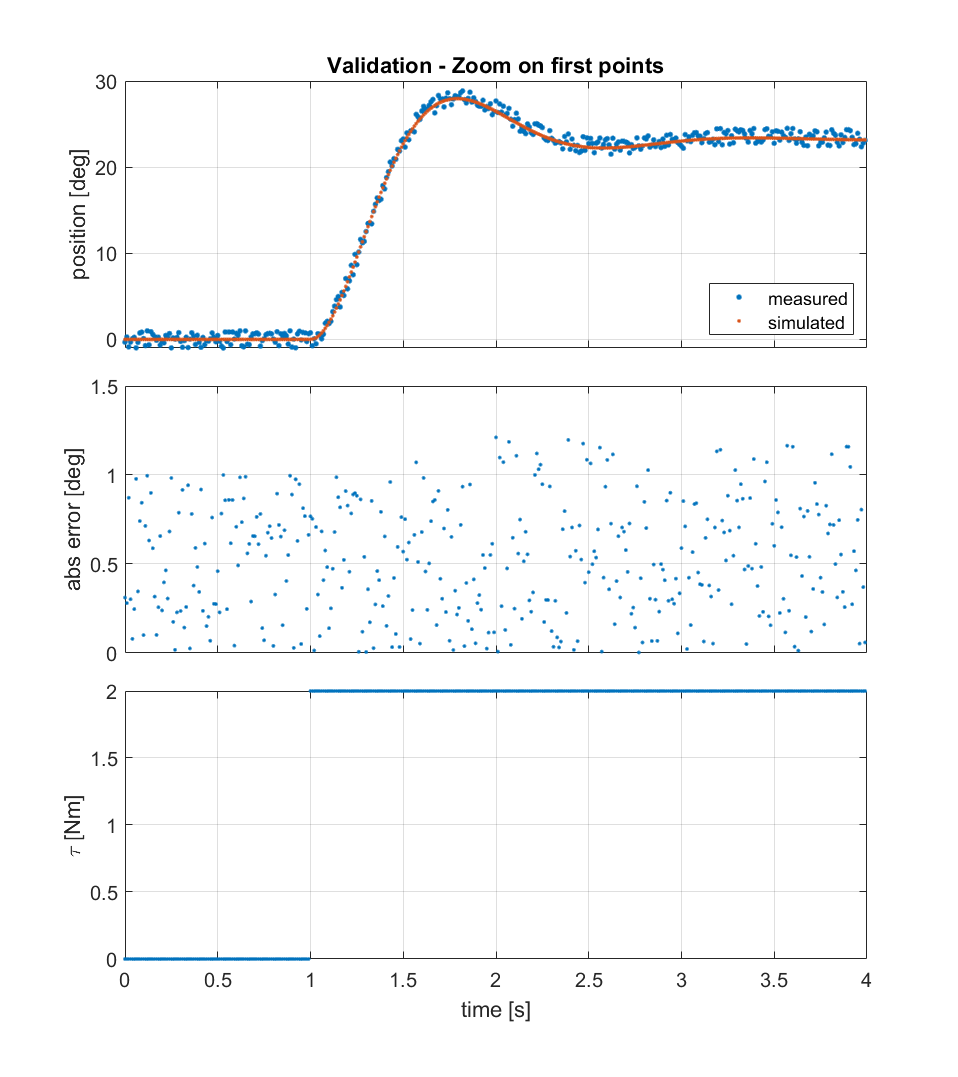

%% Plots
figure;
tiledlayout(3, 1, 'TileSpacing', 'compact');

clearvars ax;
ax(1) = nexttile; hold on; grid on; box on;
title('Validation - Zoom on first points')
hold all, grid on, box on;
set(gca,'DefaultLineLineWidth', 0.5,'FontSize',12);                                                       
ylabel('position [deg]');
plot(time(1:4/Ts),y_val(1:4/Ts)*180/pi,'.','MarkerSize', 10)
plot(time(1:4/Ts),y_val_hat(1:4/Ts)*180/pi,'.');
legend('measured','simulated','location','SouthEast');

ax(2) = nexttile; hold on; grid on; box on;
set(gca,'DefaultLineLineWidth', 0.5,...
    'FontSize',12);                                              
ylabel('abs error [deg]');
plot(time(1:4/Ts),abs(y_val_hat(1:4/Ts)-y_val(1:4/Ts))*180/pi,'.');

ax(3) = nexttile; hold on; grid on; box on;
set(gca,'DefaultLineLineWidth', 0.5,...
    'FontSize',12);
xlabel('time [s]');                                                         
ylabel('\tau [Nm]');
plot(time(1:4/Ts),u_val(1:4/Ts),'.');

set(gcf,'position',[0,0,800,900]);

ax(1).XTickLabel = '';
ax(2).XTickLabel = '';
linkaxes(ax,'x'); clear ax;  clf;

In this case, we obtain similar results with the ones obtained by considering the impulse response. Indeed, the error between the measured and estimated output is solely linked to the presence of noise in the measured output, as before.

## Question examples:

- Given a MATLAB vector *y_ir* containing the impulse response of a *noiseless* system, write the code for the Hankel matrix of order 3. Suppose that its rank is equal to 2: write the code to find $R_3$.

- Given a Hankel matrix *H_qd* with *d* columns and* q* rows and the system order *n*, compute $\hat{O}$ and $\hat{R}$. Then compute $\hat{F}$, $\hat{G}$, $\hat{H}$ and $\hat{D}$.

- In MATLAB, given the extended observability and reachability matrices $O_4 \;$and $R_4$ of a system of order 3, write the code to find the system matrices F, G, H and D. Then write the code to find the system transfer function.

- You are given a generic dataset containing the input and output timeseries signals of a system: *u_vec* and *y_vec*. The sampling frequency of the vectors is 10 Hz. Write the MATLAB code to identify the system using the 4SID method and display the identified system in zero-pole-gain form.